# Atividade 13_01

Otávio Baziewicz Filho - 1942808

clc; clear; close all;

## Suavização de imagens coloridas

Crie um script para suavizar uma imagem colorida à sua escolha. Mostre a imagem original e a imagem suavizada.

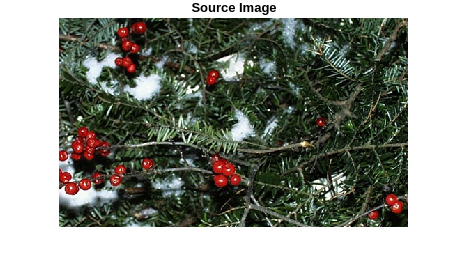

img = imread("greens.jpg");

r = img(:,:,1);
g = img(:,:,2);
b = img(:,:,3);

h = fspecial("gaussian", [5 5], 1);

rlp = imfilter(r, h);
glp = imfilter(g, h);
blp = imfilter(b, h);

processedImage = cat(3, rlp, glp, blp);

figure, imshow(img), title("Source Image")

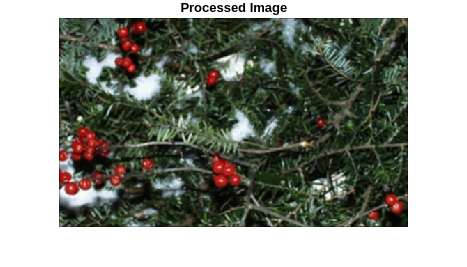

figure, imshow(processedImage), title("Processed Image")